## Import transder functions from Simulink models PC

### Elevation pod

Elevation_pod_PC_model ='Pod_elev_PC_linear';
io(1)=linio('Pod_elev_PC_linear/input_current_controller_pod_elev',1,'input');
io(2)=linio('Pod_elev_PC_linear/Pod_elev_plant_linear',1,'output');
simulation_POD_Elevation_PC_to_gyro = linearize(Elevation_pod_PC_model,io);

tf_epod_current_gyro_PC=tf(simulation_POD_Elevation_PC_to_gyro);

### Elevation Gun

Elevation_Gun_model_PC = 'Gun_elev_PC_linear';
io(1)=linio('Gun_elev_PC_linear/Input_current_elev_PC',1,'input');
io(2)=linio('Gun_elev_PC_linear/GUN_ELEV_PLANT_FOR_PC_gyro',1,'output');
simulation_GUN_Elevation_PC_to_gyro = linearize(Elevation_Gun_model_PC,io);

io(2)=linio('Gun_elev_PC_linear/GUN_ELEV_PLANT_FOR_PC_techo',2,'output');
simulation_GUN_Elevation_PC_to_engineV = linearize(Elevation_Gun_model_PC,io);

tf_egun_current_gyro_PC=tf(simulation_GUN_Elevation_PC_to_gyro);
tf_egun_current_techo_PC=tf(simulation_GUN_Elevation_PC_to_engineV);

### Traverse Gun

Trav_Gun_PC_model = 'Gun_trav_PC_linear';
io(1)=linio('Gun_trav_PC_linear/Input_PC_trav',1,'input');
io(2)=linio('Gun_trav_PC_linear/GUN_PLANT_FOR_PC_GYRO',1,'output');
simulation_GUN_trav_PC_to_gyro = linearize(Trav_Gun_PC_model,io);

io(2)=linio('Gun_trav_PC_linear/GUN_PLANT_FOR_PC_TECHO',2,'output');
simulation_GUN_trav_PC_to_techo = linearize(Trav_Gun_PC_model,io);


tf_tgun_current_gyro_PC=tf(simulation_GUN_trav_PC_to_gyro);
tf_tgun_current_techo_PC=tf(simulation_GUN_trav_PC_to_techo);


### Plots

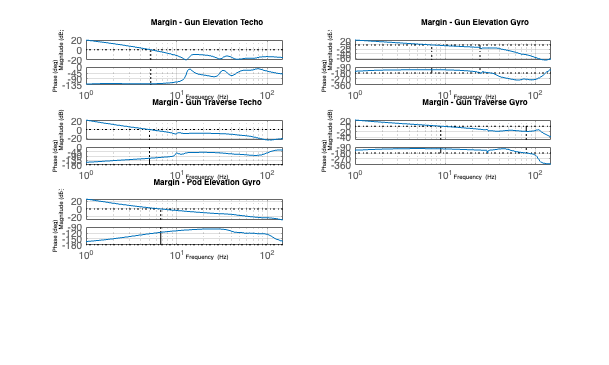

figure('Position', [10 10 1000 600]);

sub_plot_rows=4;
sub_plot_col=2;


opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
opts.XLabel.FontSize = 6;
opts.YLabel.FontSize = 6;
opts.InputLabels.Color='white';
opts.Grid='on';
opts.Xlim={[1,150]};
font_title_size=8;




%plot bode_gun_elevation

subplot(sub_plot_rows,sub_plot_col,1)
margin(tf_egun_current_techo_PC,opts)
title('Margin - Gun Elevation Techo', 'FontSize', font_title_size)

subplot(sub_plot_rows,sub_plot_col,2)
margin(tf_egun_current_gyro_PC,opts)
title('Margin - Gun Elevation Gyro', 'FontSize', font_title_size)

%plot bode_gun_traverse
subplot(sub_plot_rows,sub_plot_col,3)
margin(tf_tgun_current_techo_PC,opts)
title('Margin - Gun Traverse Techo', 'FontSize', font_title_size)

subplot(sub_plot_rows,sub_plot_col,4)
margin(tf_tgun_current_gyro_PC,opts)
title('Margin - Gun Traverse Gyro', 'FontSize', font_title_size)

%plot bode_pod_traverse


subplot(sub_plot_rows,sub_plot_col,5)
margin(tf_epod_current_gyro_PC,opts)
title('Margin - Pod Elevation Gyro', 'FontSize', font_title_size)